# 変換としての行列(2)

clear;clc;close all;

figure;
tiledlayout(2,2);

for tileNum=1:4
    switch tileNum
        case 1
            A=[1 2;2 1];

        case 2
            A=[2 -1;-1 2];

        case 3
            A=[1 -1;1 1];

        case 4
            A=[2 -1;2 -1];
    end
    matText=latex(sym(A));
    nexttile

    hold on;
    set(gca,'fontname','メイリオ','fontsize',8);

    X=zeros(9,9);
    Y=zeros(9,9);
    Z=zeros(9,9);
    for n1=-4:4
        for n2=-4:4
            tmpV=n1*A(:,1)+n2*A(:,2);
            X(n1+5,n2+5)=tmpV(1);
            Y(n1+5,n2+5)=tmpV(2);
            Z(n1+5,n2+5)=0;

        end
    end
    mesh(X,Y,Z,'FaceAlpha',0,'EdgeColor','g');view(0,90)
    hold on;
    grid on;axis equal;
    axis(3*[-1 1 -1 1]);
    xticks(-3:3);yticks(-3:3);
    pgon = polyshape([0 0 1 1],[1 0 0 1]);
    plot(pgon,'FaceAlpha',0.3)
    quiver(0, 0, 1, 0, 'b-','LineWidth',1.5,'AutoScale','off');
    quiver(0, 0, 0, 1, 'b-','LineWidth',1.5,'AutoScale','off');

    pgon2 = polyshape([0 A(1,1), A(1,1)+A(1,2), A(1,2)], ...
        [0 A(2,1), A(2,1)+A(2,2), A(2,2)]);
    plot(pgon2,'FaceAlpha',0.3)
    quiver(0, 0, A(1,1), A(2,1), 'r-','LineWidth',1.5,'AutoScale','off');
    quiver(0, 0, A(1,2), A(2,2), 'r-','LineWidth',1.5,'AutoScale','off');

    xlabel('$x_1$','Interpreter','latex','FontSize',12)
    ylabel('$x_2$','Interpreter','latex','FontSize',12)
    title(['(' num2str(tileNum)   ')'])
    text(-2,-2,['$A=' matText '$'],'Interpreter','latex')
end

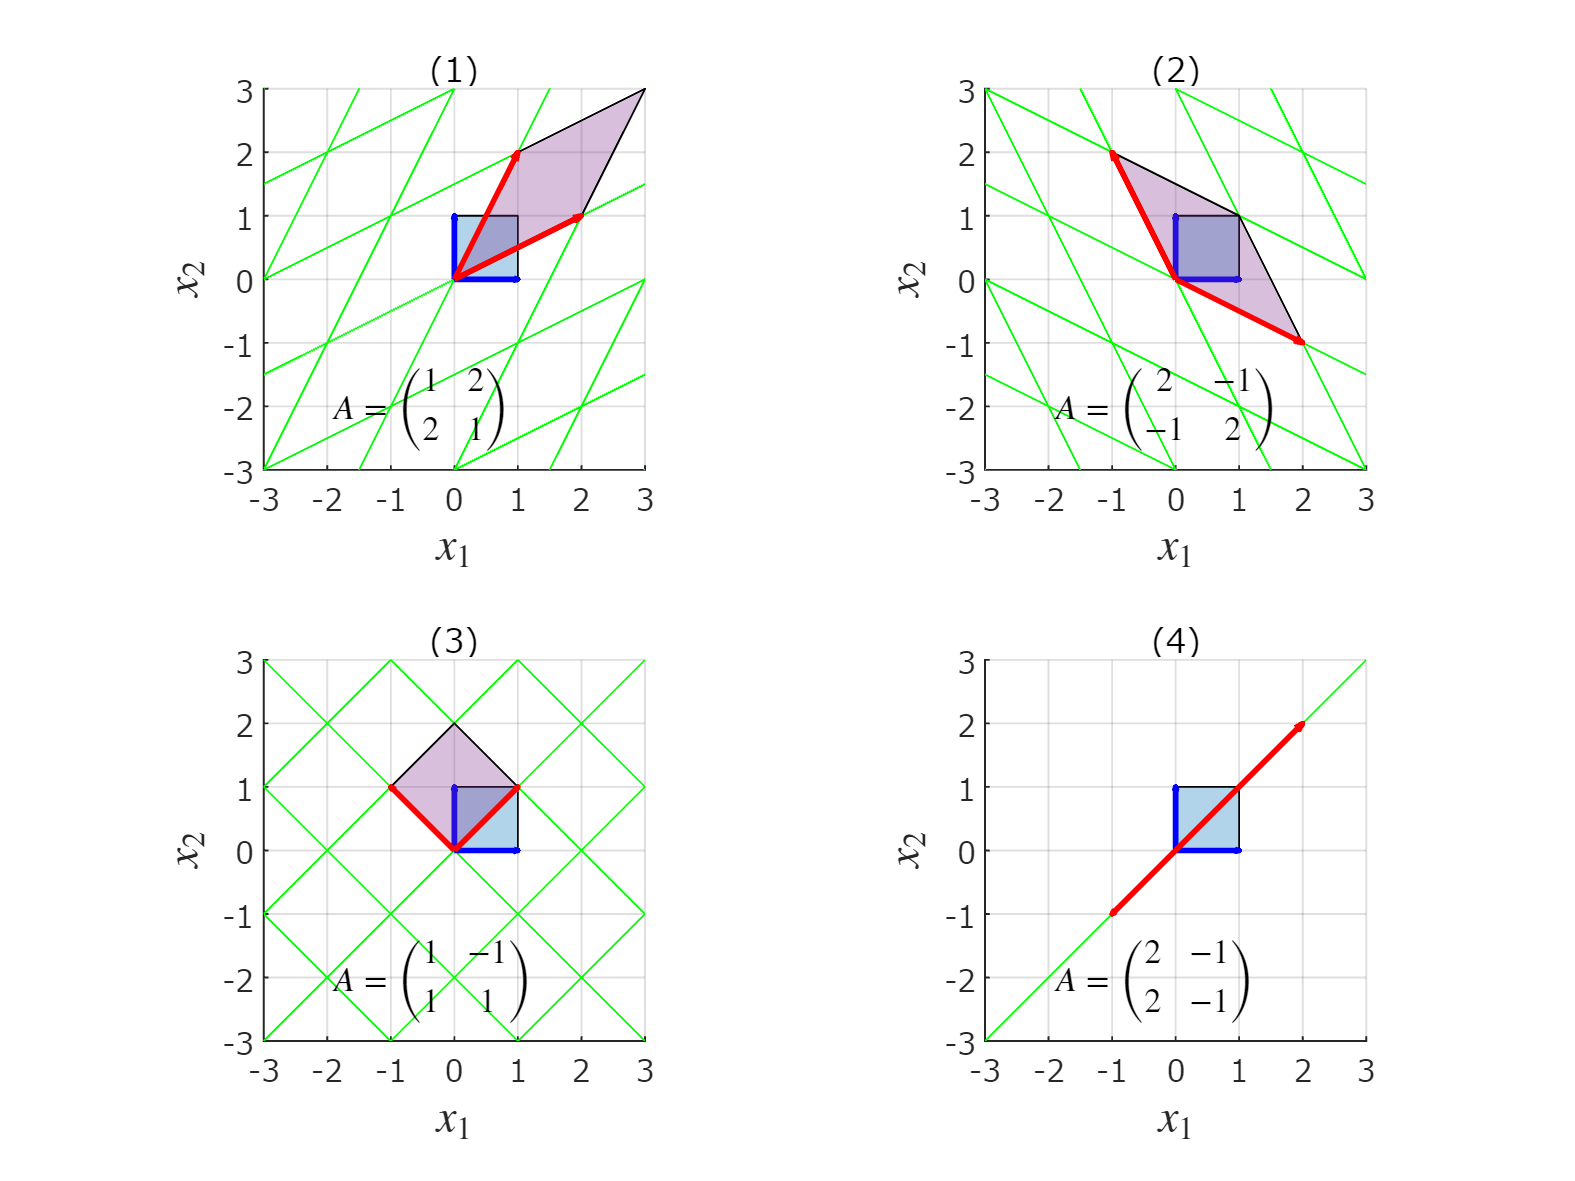


exportgraphics(gcf,'fig_linearTransformationSample02.pdf')